%Build Alpha 1.0 - Improved-Guide Detection (2019-11-23)

%[TestCode, encode] = GenerateCode('Toronto,ON');

%TestImage1 = imread('im4.jpg');
%TestImage1 = imread('im4.png');
%TestImage1 = imread('image3.png');
TestImage1 = imread("training_2.jpg");

TestImage1 = imsharpen(TestImage1);

TestImage1 = imresize(TestImage1, 0.8);
%TestImage1 = imrotate(TestImage1, -90);

TestG = rgb2gray(TestImage1);

L2 = imbinarize(TestG, 'adaptive','ForegroundPolarity','dark','Sensitivity',0.5);
L2 = xor(ones(size(TestG)), L2);

AveFilter = ones(3,3)*1/9;
L2 = imfilter(L2, AveFilter);

se = strel('disk', 1, 8);

L2 = imerode(L2, se);

se = strel('disk', 1, 8);
%L2 = medfilt2(L2);
L2 = imdilate(L2, se);
%imshow(L2);


% bw = edge(TestG);
% 
% MaxPixels = 5;
% %L2 = edge(TestG);
% [L,num] = bwlabel(bw);
% 
% counts = sum(bsxfun(@eq,L(:),1:num));
% B1 = bsxfun(@eq,L,permute(find(counts>MaxPixels),[1 3 2]));
% L2 = sum(B1,3)>0;

%Find regions
s = regionprops(L2,{...
    'Area', ...
    'Centroid',...
    'MajorAxisLength',...
    'MinorAxisLength',...
    'Orientation', ... 
    'Solidity'});

TotalShapes = length(s);

Guidelines = struct;
GuidelinesS = struct;
GuidelinesL = struct;
Cornerstones = struct;

% GuidelinesS.Centroid = [0 0];
% GuidelinesS.MajorAxisLength = 0;
% GuidelinesS.MajorAxisLength = 0;
% GuidelinesS.Orientation = 0;

MinSRatio = 3;
MaxSRatio = 10;

MinLRatio = 6;
MaxLRatio = 10;

PotentialGuideS = 0;
PotentialGuideL = 0;
PotentialCornerstones = 0;

for i = 1:TotalShapes
    Shape = s(i);
    ShapePos = Shape.Centroid;
    ShapeLength = Shape.MajorAxisLength;
    ShapeWidth = Shape.MinorAxisLength;
    ShapeAngle = Shape.Orientation;
    ShapeSolid = Shape.Solidity;
    
    %Get Ratio
    ShapeRatio = ShapeLength/ShapeWidth;
    
    %Store Guides
    if ShapeRatio > MinSRatio && ShapeRatio < MaxSRatio && ShapeSolid > 0.6 && Shape.Area > 6
        PotentialGuideS = PotentialGuideS + 1;

        GuidelinesS(PotentialGuideS).Centroid = ShapePos;
        GuidelinesS(PotentialGuideS).MajorAxisLength = ShapeLength;
        GuidelinesS(PotentialGuideS).MinorAxisLength = ShapeWidth;
        GuidelinesS(PotentialGuideS).Orientation = ShapeAngle;
        GuidelinesS(PotentialGuideS).Solidity = ShapeSolid;
        
%     elseif ShapeRatio > MinLRatio && ShapeRatio < MaxLRatio && ShapeSolid > 0.6 && Shape.Area > 6
%         PotentialGuideL = PotentialGuideL + 1;
%         GuidelinesL(PotentialGuideL).Centroid = ShapePos;
%         GuidelinesL(PotentialGuideL).MajorAxisLength = ShapeLength;
%         GuidelinesL(PotentialGuideL).MinorAxisLength = ShapeWidth;
%         GuidelinesL(PotentialGuideL).Orientation = ShapeAngle;
%         GuidelinesL(PotentialGuideL).Solidity = ShapeSolid;
        
    else
        %Check cornerstones
        if ShapeRatio > 0.7 && ShapeRatio < 1.2 && ShapeSolid > 0.6 && Shape.Area > 6
            PotentialCornerstones = PotentialCornerstones + 1;
            
            Cornerstones(PotentialCornerstones).Centroid = ShapePos;
            Cornerstones(PotentialCornerstones).MajorAxisLength = ShapeLength;
            Cornerstones(PotentialCornerstones).MinorAxisLength = ShapeWidth;
            Cornerstones(PotentialCornerstones).Orientation = ShapeAngle;
            Cornerstones(PotentialCornerstones).Solidity = ShapeSolid;
        end

    end
end

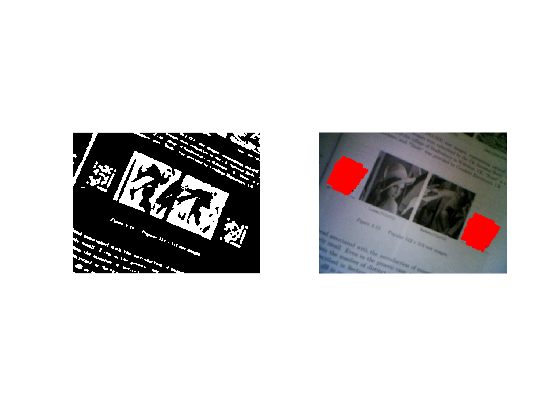


% TotalS = 0;
% TotalL = 0;
PotentialMarkers = 0;
Guides = struct;
%ConfirmedMarkers = struct;

%Verify Guides
for GuideS = 1:PotentialGuideS
    S = GuidelinesS(GuideS);
    SPos = S.Centroid;
    SLength = S.MajorAxisLength;
    SWidth = S.MinorAxisLength;
    SAngle = S.Orientation;
    %SSolid = Shape.Solidity;
    
    %Look for matching long guide
    for GuideL = 1:PotentialGuideS
        L = GuidelinesS(GuideL);
        LPos = L.Centroid;
        LLength = L.MajorAxisLength;
        LWidth = S.MinorAxisLength;
        LAngle = L.Orientation;
        
        
        AveWidth = (SWidth + LWidth)/2;
        
        dRatio = LLength/SLength;
        dGuide = norm(SPos - LPos);
        dAngle = abs(SAngle - LAngle);
        
        Min = 2.5*AveWidth;
        Max = 8*AveWidth;
        
        if dGuide >=  Min && dGuide <  Max ...
            && dAngle > 75 && dAngle < 100 ...
            && dRatio > 1.1 && dRatio < 1.6
        
            PotentialMarkers = PotentialMarkers + 1;
            
            Guides(PotentialMarkers).SGuide = GuidelinesS(GuideS);
            Guides(PotentialMarkers).LGuide = GuidelinesS(GuideL);
            
        end
    end
end

ConfirmedMarkers = 0;

%Find Cornerstones
for G = 1:PotentialMarkers
    GuideS = Guides(G).SGuide;
    GuideL = Guides(G).LGuide;
    
    for A = 1:PotentialCornerstones
        for B = 1:PotentialCornerstones
            for C = 1:PotentialCornerstones
                APos = Cornerstones(A).Centroid;
                BPos = Cornerstones(B).Centroid;
                CPos = Cornerstones(C).Centroid;
                
                AveWidth = (Cornerstones(A).MinorAxisLength + Cornerstones(B).MinorAxisLength ...
                            + Cornerstones(C).MinorAxisLength)/3;
                
                dAB = norm(APos - BPos);
                dAC = norm(APos - CPos);
                dCB = norm(CPos - BPos);
                dCS = norm(CPos - GuideS.Centroid);
                dBL = norm(BPos - GuideL.Centroid);
                
                Angle = acos((dAB^2 + dAC^2 - dCB^2)/(2*dAB*dAC))*180/pi;
                
                MinSide = 7*AveWidth;
                MaxSide = 12*AveWidth;
                
                MinDiag = 10*AveWidth;
                MaxDiag = 17*AveWidth;
                
                MinL = 3*AveWidth;
                MaxL = 7*AveWidth;
                
                MinS = 6*AveWidth;
                MaxS = 10*AveWidth;
                
                if dAB > MinSide && dAB < MaxSide 
                    if dAC > MinSide && dAC < MaxSide 
                        if dCB > MinDiag && dCB < MaxDiag 
                            if dCS > MinS && dCS < MaxS  
                                if dBL > MinL && dBL < MaxL ...
                                    && Angle > 75 && Angle < 100
                    
                                ConfirmedMarkers = ConfirmedMarkers + 1;
                           
                                Guides(G).A = Cornerstones(A);
                                Guides(G).B = Cornerstones(B);
                                Guides(G).C = Cornerstones(C);
                                end
                            end
                        end
                    end
                end
            end
        end
    end
end
subplot(1,2,1);
imshow(L2);

SamplingGrid = zeros(11,11,2);

%Plot markers
subplot(1,2,2);
imshow(TestImage1);
hold on
for i = 1:PotentialMarkers
    Pos1 = Guides(i).SGuide.Centroid;
    Pos2 = Guides(i).LGuide.Centroid;
    Pos3 = Guides(i).A.Centroid;
    Pos4 = Guides(i).B.Centroid;
    Pos5 = Guides(i).C.Centroid;
    
    VectorX = SampleInterval(Pos3, Pos4, 11);
    VectorY = SampleInterval(Pos3, Pos5, 11);
    VectorZ = SampleInterval(Pos4, Pos1, 11);
    VectorA = SampleInterval(Pos5, Pos1, 9);
    
    %Generate Inbetween sampling points
    for k = 2:11
        P1 = [VectorY(1,k) VectorY(2,k)];
        P2 = [VectorZ(1,k) VectorZ(2,k)];
        
        if k <= 4
            NumSample = 11;
        elseif k>4 && k <= 8
            NumSample = 10;
        else
            NumSample = 9;
        end
        
        SampleVector = SampleInterval(P1, P2, NumSample);
        
        SamplingGrid(k, :, 1) = SampleVector(1, :);
        SamplingGrid(k, :, 2) = SampleVector(2, :);
    end
    
    SamplingGrid(1, :, 1) = VectorX(1, :);
    SamplingGrid(1, :, 2) = VectorX(2, :);
    
    for j = 1:11
        for k = 1:11
            plot(SamplingGrid(j,k,1), SamplingGrid(j,k,2), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
            
            
        end
    end
    
    
%     for j = 1:length(Vector)
%         plot(VectorX(1, j), VectorX(2,j), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%         plot(VectorY(1, j), VectorY(2,j), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%         plot(VectorZ(1, j), VectorZ(2,j), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%         
%         if j <= 8
%             plot(VectorA(1, j), VectorA(2,j), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%     
%         end
%     end
%     plot(Pos1(1), Pos1(2), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%     plot(Pos2(1), Pos2(2), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%     plot(Pos3(1), Pos3(2), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%     plot(Pos4(1), Pos4(2), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
%     plot(Pos5(1), Pos5(2), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
end
hold off


% %Verify Shapes
% for j = 1:PotentialGuideS
%     Shape = Guidelines(j);
%     ShapePos = Shape.Centroid;
%     ShapeLength = Shape.MajorAxisLength;
%     ShapeWidth = Shape.MinorAxisLength;
%     ShapeAngle = Shape.Orientation;
%     
%     for k = 1:PotentialGuideS
%         Shape2 = Guidelines(k);
%         ShapePos2 = Shape2.Centroid;
%         ShapeLength2 = Shape2.MajorAxisLength;
%         ShapeWidth2 = Shape2.MinorAxisLength;
%         ShapeAngle2 = Shape2.Orientation;
%         
%         dGuide = norm(ShapePos - ShapePos2);
%         dAngle = abs(ShapeAngle - ShapeAngle2);
%         
%         Min = 2.5*ShapeWidth;
%         Max = 7*ShapeWidth;
%         
%         if dGuide >=  Min && dGuide <  Max ...
%             && dAngle > 75 && dAngle < 100
%        
%             %Short
%             if  ShapeLength < ShapeLength2
%                 TotalS = TotalS + 1;
%                 GuidelinesS(TotalS).Centroid = ShapePos;
%                 GuidelinesS(TotalS).MajorAxisLength = ShapeLength;
%                 GuidelinesS(TotalS).MinorAxisLength = ShapeWidth;
%                 GuidelinesS(TotalS).Orientation = ShapeAngle;
%             end
%             
%             %Long
% %             if ShapeLength > ShapeLength2
% %                 TotalL = TotalL + 1;
% %                 GuidelinesL(TotalL).Centroid = ShapePos2;
% %                 GuidelinesL(TotalL).MajorAxisLength = ShapeLength2;
% %                 GuidelinesL(TotalL).MinorAxisLength = ShapeWidth2;
% %                 GuidelinesL(TotalL).Orientation = ShapeAngle2;
% %             end
%         end
%         
%     end
%     
% end

% ConfirmedMarkers = zeros(length(s), 4);
% TotalMarkers = 0;
% 
% %Verify Cornerstones
% for Apex = 1:PotentialCornerstones
%     Shape = Cornerstones(Apex);
%     ShapePos = Shape.Centroid;
%     
%     for CornerA = 1:PotentialCornerstones
%         ShapeA = Cornerstones(CornerA);
%         ShapePosA = ShapeA.Centroid;
%         
%         for CornerB = 1:PotentialCornerstones
%             ShapeB = Cornerstones(CornerB);
%             ShapePosB = ShapeB.Centroid;
%             
%             dApexA = norm(ShapePos - ShapePosA);
%             dApexB = norm(ShapePos - ShapePosB);
%             dCorner = norm(ShapePosA - ShapePosB);
%             
%             Angle = acos((dApexA^2 + dApexB^2 - dCorner^2)/(2*dApexA*dApexB))*180/pi;
%             
%             Max = Shape.MinorAxisLength*14;
%             Min = Shape.MinorAxisLength*6;
%             
%             MaxC = Shape.MinorAxisLength*12;
%             MinC = Shape.MinorAxisLength*6;
%             
%             if Angle > 75 && Angle < 100 ...
%                     && dApexA > Min && dApexA < Max ...
%                         && dApexB > Min && dApexB < Max ...
%                             && dCorner > MinC && dCorner < MaxC
%                         
%                         %Find Matching Short Guide Bar
%                         for Guide = 1:TotalS
%                             GuidePos = GuidelinesS(Guide).Centroid;
%                             
%                             dApexGuide = norm(GuidePos - ShapePos);
%                             dCornerAGuide = norm(GuidePos - ShapePosA);
%                             dCornerBGuide = norm(GuidePos - ShapePosB);
%                             
%                             
%                             MaxDistance = 12*Shape.MinorAxisLength;
%                             MinDistance = 8*Shape.MinorAxisLength;
%                             
%                             if dApexGuide > MinDistance && dApexGuide < MaxDistance ...
%                                     && dCornerBGuide > dCornerAGuide
%                                 TotalMarkers = TotalMarkers + 1;
%                                 ConfirmedMarkers(TotalMarkers, :) = [Apex CornerA CornerB Guide];
%                             end
%                         end
%             end
%         end
%     end
% end
% 
% NumSamples = 11;
% Code = uint8(zeros(NumSamples, NumSamples));
% Code2 = Code;
% 
% Factor = 1.1;
% 
% imshow(L2);
% hold on;
% 
% 
% 
% %Get Marker
% for Marker = 1:TotalMarkers
%     ApexPos = Cornerstones(ConfirmedMarkers(Marker, 1)).Centroid;
%     APos = Cornerstones(ConfirmedMarkers(Marker, 2)).Centroid;
%     BPos = Cornerstones(ConfirmedMarkers(Marker, 3)).Centroid;
%     GCenter = GuidelinesS(ConfirmedMarkers(Marker, 4)).Centroid;
%     GAngle = abs(GuidelinesS(ConfirmedMarkers(Marker, 4)).Orientation);
%     
%     GPosX = GuidelinesS(ConfirmedMarkers(Marker, 4)).MajorAxisLength/2*cosd(GAngle) + GCenter(1);
%     GPosY = GuidelinesS(ConfirmedMarkers(Marker, 4)).MajorAxisLength/2*sind(GAngle) + GCenter(2);
%     GPos = [GPosX*0.97 GPosY];
%     
%     %TestSample = SampleInterval(ApexPos, BPos, 11);
%     Test = SamplingGrid(ApexPos, BPos, APos, GPos, 11);
%     
%     name = 'MarkerX.png';
%     
%     for Row = 1:11
%         for Col = 1:11
%             name(7) = string(Marker);
%             
%             plot(Test(Row,Col,1), Test(Row,Col,2), 'r+', 'LineWidth', 2, 'MarkerSize', 10);
% %            Code(Row, Col) = TestImage1(Test(Row,Col,2), Test(Row,Col,1));
%             
%             if Marker == 2
%                 Code2(Row, Col) = TestImage1(Test(Row,Col,2), Test(Row,Col,1));
%             else
%                 Code(Row, Col) = TestImage1(Test(Row,Col,2), Test(Row,Col,1));
%             end
%             
%             %Code = imcomplement(imbinarize(Code,100));
%             %imwrite(Code, name);
%         end
%     end
% end
% hold off;
% 
% 
% 
% [Msg, decode] = QRDecode(Code);
% %CodeMsg2 = QRDecode(Code2);
% 
% % VerCode = zeros(2,83);
% % VerCode(1,:) = encode;
% % VerCode(2,:) = decode;
% 
% imshow(Code);
%sgtitle(CodeMsg);

% imshow(Code2);
% sgtitle(CodeMsg2);
% 
% VerCode = uint8(TestCode) - Code;
% imshow(VerCode);
% sgtitle('Error Pixels');
% imshow(Row);
% t = linspace(0,2*pi,50);
% 
% s = GuidelinesS;
% 
% imshow(TestImage1);
% hold on
% for k = 1:length(s)
%     a = s(k).MajorAxisLength/2;
%     b = s(k).MinorAxisLength/2;
%     Xc = s(k).Centroid(1);
%     Yc = s(k).Centroid(2);
%     phi = deg2rad(-s(k).Orientation);
%     x = Xc + a*cos(t)*cos(phi) - b*sin(t)*sin(phi);
%     y = Yc + a*cos(t)*sin(phi) + b*sin(t)*cos(phi);
%     plot(x,y,'r','Linewidth',5)
% end
% 
% s = Cornerstones;
% 
% for k = 1:length(s)
%     a = s(k).MajorAxisLength/2;
%     b = s(k).MinorAxisLength/2;
%     Xc = s(k).Centroid(1);
%     Yc = s(k).Centroid(2);
%     phi = deg2rad(-s(k).Orientation);
%     x = Xc + a*cos(t)*cos(phi) - b*sin(t)*sin(phi);
%     y = Yc + a*cos(t)*sin(phi) + b*sin(t)*cos(phi);
%     plot(x,y,'r','Linewidth',5)
% end
% hold off